# **Analisi preliminare**

## **Reset del workspace**

clear all %#ok<CLALL> 
clc

## Importazione dei dati

load('../Data/Processed data/Hourly_data.mat')
transport_ST = readtable('../Data/Sources/Train stations/Jersey_City_train_stations_data.csv');

## Processamento dei dati

### Dati meteorologici

weather_vars = {'X_beta_avg_feels_like_T', 'X_beta_rainfall', ...
    'X_beta_visibility', 'X_beta_windspeed', 'X_beta_cloud_cover'};
dates = unique(hourly_data.Time);
daily_weather_data = array2table(zeros(length(dates), length(weather_vars)));
daily_weather_data.Properties.VariableNames = weather_vars;
daily_weather_data.Time = dates;
for i=1:length(dates)
    temp = hourly_data(hourly_data.Time == dates(i), weather_vars);
    temp = temp(1, :);
    for j=1:length(weather_vars)
        daily_weather_data{i, j} = mean(temp{1, weather_vars{j}}{1});
    end
end

### Numero di ritiri

#### Per stazione (somma giornaliera)

n = size(unique(hourly_data(:, {'X_coordinate', 'Y_coordinate'})), 1);
daily_pickups_by_station = array2table(zeros(length(dates), n));
daily_pickups_by_station.Properties.VariableNames = arrayfun(@(x) ['S' num2str(x)], 1:n, 'UniformOutput', false);
daily_pickups_by_station.Time = dates;
for i=1:length(dates)
    temp = hourly_data(hourly_data.Time == dates(i), 'Y');
    for j=1:n
        daily_pickups_by_station{i, j} = sum(temp{j, 1}{:});
    end
end

#### Per ora (media sulle stazioni)

daily_mean_pickups_by_hour = array2table(zeros(length(dates), 24));
daily_mean_pickups_by_hour.Properties.VariableNames = arrayfun(@(x) ['H' num2str(x)], 0:23, 'UniformOutput', false);
daily_mean_pickups_by_hour.Time = dates;
for i=1:length(dates)
    temp = hourly_data(hourly_data.Time == dates(i), 'Y');
    means = mean(cell2mat(table2cell(temp)), 1);
    for j=1:24
        daily_mean_pickups_by_hour{i, j} = means(j);
    end
end

### Variabili dummy

dummy_vars = {'X_beta_holidays', 'X_beta_lockdown', 'X_beta_happy'};
days_info = array2table(zeros(length(dates), length(dummy_vars)));
days_info.Properties.VariableNames = dummy_vars;
days_info.Time = dates;
for i=1:length(dates)
    temp = hourly_data(hourly_data.Time == dates(i), dummy_vars);
    temp = temp(1, :);
    for j=1:length(dummy_vars)
        days_info{i, j} = max(temp{1, dummy_vars{j}}{1});
    end
end

### Variabili spaziali

spatial_vars = {'X_beta_ts_distance', 'X_beta_dem'};
spatial_data = array2table(zeros(n, length(spatial_vars)));
spatial_data.Properties.VariableNames = spatial_vars;
spatial_data = horzcat(spatial_data, hourly_data(1:n, {'X_coordinate', 'Y_coordinate'}));
for i=1:n
    for j=1:length(spatial_vars)
        spatial_data{i, j} = hourly_data{i, spatial_vars{j}}{:}(1);
    end
end

## Mappe

### Punti di ritiro e stazioni del treno

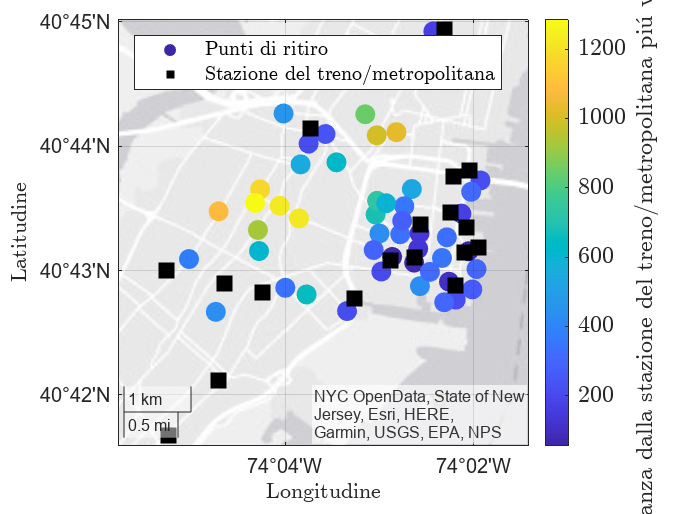

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
s = geoscatter(spatial_data, "Y_coordinate", "X_coordinate", "filled");
s.ColorVariable = "X_beta_ts_distance";
s.SizeData = 100;
gx = s.Parent;
gx.LatitudeLabel.String = "Latitudine";
gx.LatitudeLabel.Interpreter = "latex";
gx.LongitudeLabel.String = "Longitudine";
gx.LongitudeLabel.Interpreter = "latex";
c = colorbar;
c.Label.String = "Distanza dalla stazione del treno/metropolitana pi\'u vicina [m]";
c.Label.Interpreter = "latex";
c.FontSize = 12;
c.TickLabelInterpreter = "latex";

hold on
g = geoscatter(transport_ST, "Lat", "Lon", "filled", "Marker", "square",...
    "MarkerFaceColor", "k");
g.SizeData = 100;
legend("Punti di ritiro", "Stazione del treno/metropolitana", "FontSize", 10,...
    "Interpreter", "latex", 'Location', 'northwest')

### Densità abitativa

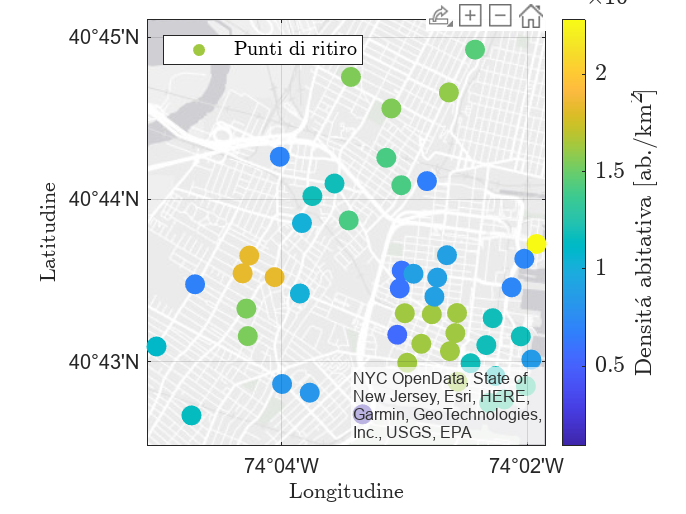

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
s = geoscatter(spatial_data, "Y_coordinate", "X_coordinate", "filled");
s.ColorVariable = "X_beta_dem";
s.SizeData = 100;
gx = s.Parent;
gx.LatitudeLabel.String = "Latitudine";
gx.LatitudeLabel.Interpreter = "latex";
gx.LongitudeLabel.String = "Longitudine";
gx.LongitudeLabel.Interpreter = "latex";
c = colorbar;
c.Label.String = "Densit\'a abitativa [ab./km$^2$]";
c.Label.Interpreter = "latex";
c.FontSize = 12;
c.TickLabelInterpreter = "latex";
legend("Punti di ritiro", "FontSize", 10,...
    "Interpreter", "latex", 'Location', 'northwest')